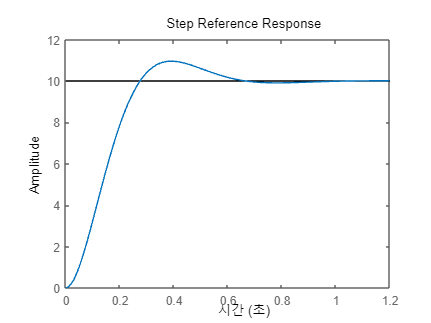

s= tf('s');
K=100.4742;
K1=12;
t_system = 0:0.01:1.2;
P_system = 1/(s*(s+K1));
r_system = 10;

P_system = P_cruise;

C = K;
sys_cl = feedback(C*P_system,1);
figure(1)
step(r_system*sys_cl,t_system);
ylabel('Amplitude')
title('Step Reference Response');

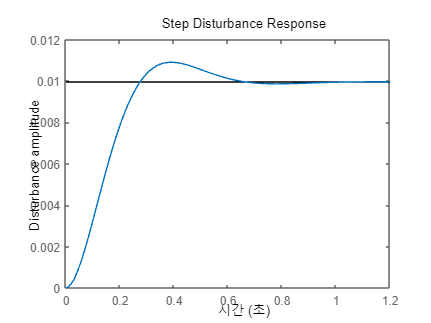

figure(2);
dist_cl=feedback(P_system,C);
step(dist_cl,t_system);
ylabel('Disturbance amplitude')
title('Step Disturbance Response')


stepinfo(sys_cl)

ans = 다음 필드를 포함한 struct :
         RiseTime: 0.1848
    TransientTime: 0.5927
     SettlingTime: 0.5927
      SettlingMin: 0.9109
      SettlingMax: 1.0956
        Overshoot: 9.5606
       Undershoot: 0
             Peak: 1.0956
         PeakTime: 0.3914


 % pidTuner(P_system,'p')